# Newton-Verfahren und Dämpfung

Wir betrachten das Newton-Verfahren zur Bestimmung einer Nullstelle einer skalaren Funktion $f$:

                  
$$x_{k+1}= x_k - \frac{f(x_k)}{f'(x_k)}, ~~~k=0,1,\ldots$$


und die Variante der Methode mit einem Dämpfungsparameter:

               
$$x_{k+1}= x_k -\lambda_k \frac{f(x_k)}{f'(x_k)}, ~~~k=0,1,\ldots$$


Die Wahl des Dämpfungsparameters $\lambda=\lambda_k$ basiert auf einer Methode wie in  Abschnitt 5.6.2 des Buches beschrieben.

Folgende Bespiele werden untersucht:

        $1.\quad f(x)=x^2-2$,  eindeutige positive Nullstelle $x^\ast=\sqrt{2}$.

        $2.\quad f(x)=e^{-x}-\sin x$, mehrere Nullstellen in [2,10].

        $3.\quad f(x)=2 x^3-16x+11$, eindeutige Nullstelle in $[-1,2]$ (zyklischer Verlauf für Startwert $x_0=-1$).

        $4.\quad f(x)=e^{-x^2}+0.5 -2 e^{-(30x-10)^2}$, Nullstellen nahe zueinander in $[0,0.5]$, große Änderungen der Ableitung.

        $5.\quad f(x)=\arctan x$, eindeutige Nullstelle $x^\ast=0$.

        $6.\quad f(x)=e^{-x+2.5}-\sin(2x)-1 $, eindeutige Nullstelle $x^\ast$ $\in [1,4.5]$. Ableitung hat Nullstellen in diesem Intervall. 

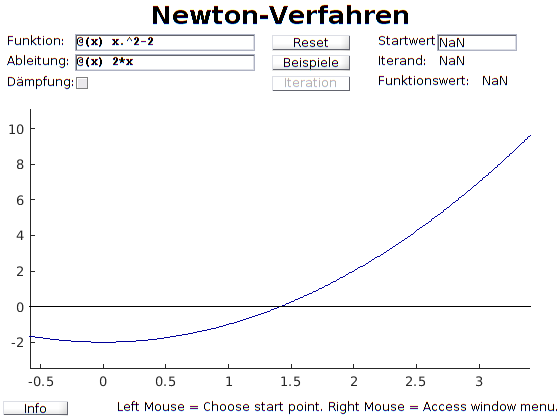

TCM_newtons_method

# Aktivität:

Drücken Sie "Run" bzw. F5, um die Demo zu starten. Wählen  Sie unterschiedliche Beispiele und variieren Sie den Startwert. Untersuchen Sie  für die  Methode ohne/mit Dämpfung die lokale Konvergenz und quadratische Konvergenzgeschwindigkeit des Newton-Verfahrens (z.B. anhand von Beispiel 5 mit $x_0=2$).

Unterstehendes MATLAB-Program **TCM_newtons_method** wurde an der Uni-Stuttgart im Rahmen des Projektes ``Teaching Calculus mit MATLAB'' entwickelt, siehe https://pnp.mathematik.uni-stuttgart.de/imng/TCM/

function TCM_newtons_method

% TCM_NEWTONS_METHOD Interactive illustration of Newton's method.
%
%   TCM_NEWTONS_METHOD illustrates the approximation of a zero of a univariate 
%   function y = f(x) using Newton's method without damping. 
%
%
%   TCM_NEWTONS_METHOD is part of the <a href="http://www2.imng.uni-stuttgart.de/LstNumGeoMod/TCM/">TCM</a> project.
%   Related course materials can be found at <a href="http://www.mathematics-online.org/inhalt/aussage/aussage3">Mathematics Online</a>.

% Authors: Florian Martin, Lars von Wolff
% Last updated: 27.06.2016
%Modified by Arnold Reusken November 2020

% Initialize data
TCM_Data.move = 0;
TCM_Data.maxsteps = 0;
TCM_Data.seq = NaN;  
TCM_Data.seqnd = NaN;  
TCM_Data.value = NaN;
TCM_Data.fun = @(x) exp(-x)-sin(x);  
TCM_Data.funstring = '@(x) exp(-x)-sin(x)';  
TCM_Data.der = @(x) -exp(-x)-cos(x);  
TCM_Data.derstring = '@(x) -exp(-x)-cos(x)'; 
TCM_Data.dampening = 0;      % damped version on/off
TCM_Data.lambda = 1;
TCM_Data.figure = 1;
TCM_Data.keep = 1;

% Do not delete these Variables
TCM_Data.plot_window = [-1 10 -2 3];
TCM_Data.LmbMenuString = '';
TCM_Data.examples = {'1. x^2-2','2. Mehrere Nullstellen','3. Zyklischer Verlauf','4. Nullstellen nahe zueinander', ...
    '5. Arkustangens', '6. Weiteres Beispiel'};

% Layout:
% ---------------------------------------
% |               Title                 |
% | ------------ --------- ------------ |
% | | Settings | |Buttons| | Feedback | |
% | ------------ --------- ------------ |
% | ----------------------------------- |
% | |           Axis (Plot)           | |
% | ----------------------------------- |
% | Info-Button         Hint            |
% ---------------------------------------
% Initialize Layout:
TCM_UI.TitleHeightMin = 10;        % minimal height of the title
TCM_UI.TitleHeightMax = 32;        % maximal height of the title
TCM_UI.HintHeightMin = 8;          % minimal height of the hint
TCM_UI.HintHeightMax = 15;         % maximal height of the hint
TCM_UI.SettingsHeightMin = 40;     % minimal height of the feedback, buttons and 
                                   % setting panel
TCM_UI.SettingsHeightMax = 70;     % maximal height of the feedback, buttons and 
                                   % setting panel
TCM_UI.SettingsRatio = 4.5;          % aspect ratio of the settings  
                                   % (increase if more settings needed)
TCM_UI.ButtonsRatio = 1.4;         % aspect ratio of the Buttons panel
TCM_UI.FeedbackRatio = 3.4;        % aspect ratio of the feedback
TCM_UI.AxisHeightTarget = 0.73;    % desired fraction of figure 
                                   % used for the plot
TCM_UI.InfoPortion = 1/8;          % Portion of the Info Button in the last  
                                   % line
TCM_UI.Title = 'Newton-Verfahren';
TCM_UI.mono = get(0,'FixedWidthFontName');
% Strings for generating the information window
TCM_UI.Author = 'F. Martin and L. von Wolff';
TCM_UI.Date = '27.06.2016';
TCM_UI.Web = 'http://www.mathematics-online.org/inhalt/aussage/aussage3';
clf reset;      
CreateUI();

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Settings %%%%%%%%%%%%%%%%%%%%
% Text for Function
TCM_UI.funtext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.70,.3,.30],...
	'String','Funktion:',...
	'Style','text');

% Input for Function
TCM_UI.funinput=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.27,.70,.68,.30],...
	'String','',...
	'Style','edit',...
	'Callback',@function_update);

% Text for Derivative
TCM_UI.dertext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.35,.3,.30],...
	'String','Ableitung:',...
	'Style','text');

% Input for Derivative
TCM_UI.derinput=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.27,.35,.68,.30],...
	'String','',...
	'Style','edit','Callback',@function_update);

% Text for Damping
TCM_UI.damptext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.0,.3,.30],...
	'String','Dämpfung:',...
	'Style','text');

% Checkbox to enable the damped version of the algorithm
TCM_UI.damped=uicontrol('Units','normalized','Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'ForegroundColor',[0,0,0], ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.7,...
        'HorizontalAlignment','right', ...
    'Position',[.27,.0,.5,.30],...
    'String','',...
    'Callback',@dampening,...
    'Style','checkbox');

%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Buttons Panel %%%%%%%%%%%%%%%%%%%%
% Reset-Button
TCM_UI.reset=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Reset', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.70,.98,.30], ...
	'Callback',@reset,...
	'Style','pushbutton');

% Example button
TCM_UI.examples=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Beispiele', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.35,.98,.30], 'Callback',@OpenExampleMenu,...
	'Style','pushbutton');

% Next-Button
TCM_UI.next=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Iteration', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.0,.98,.30], ...
	'Callback',@nextstep,...
	'Style','pushbutton',...
    'Enable','off');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Feedback %%%%%%%%%%%%%%%%%%%%

% Text for initial x value
TCM_UI.inittext=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel,...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.1,.7,.30,.3],...
	'String',sprintf('Startwert'),...
	'Style','text');

% Input for initial x value
TCM_UI.initinput=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel,...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.40,.7,.4,.3],...
	'String',' ',...
	'Style','edit',...
    'Callback',@initial_update);

% Text for current x value
TCM_UI.xval=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.1,.35,.8,.3],...
	'String',sprintf('Iterand: %5.3e',TCM_Data.seq(end)),...
	'Style','text');

% Text for current function value
TCM_UI.funval=uicontrol('Units','normalized','Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.1,.01,.9,.3],...
	'String',sprintf('Funktionswert: %5.3e',TCM_Data.value),...
	'Style','text');

% Text for current lambda value
TCM_UI.lambdaval=uicontrol('Units','normalized','Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.4,.01,.9,.3],...
	'String',sprintf('lambda value: %5.3e',TCM_Data.lambda),...
	'Style','text',...
    'Visible','off');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Axis %%%%%%%%%%%%%%%%%%%%%%%%
TCM_UI.ax=axes('Position',[.05,.1,.9,.85],'Parent',TCM_UI.axispanel);
axis(TCM_UI.ax,'equal');
TCM_UI.modification = uicontextmenu('Callback',@reset_zoom_limits); 
TCM_UI.mpan = uimenu('Parent',TCM_UI.modification,'Label','Enable pan',...
        'Callback',@axis_context);
TCM_UI.mzoomi = uimenu('Parent',TCM_UI.modification,'Label','Enable zoom in',...
    'Callback',@axis_context); 
TCM_UI.mzoomo = uimenu('Parent',TCM_UI.modification,'Label','Enable zoom out',...
        'Callback',@axis_context); 
TCM_UI.ax.UIContextMenu = TCM_UI.modification;

% functions for smoothless zooming and panning
panfun = pan(TCM_UI.fig);
panfun.UIContextMenu = TCM_UI.modification;
set(panfun,'ActionPostCallback',@pan_modify);
zoomfun = zoom(TCM_UI.fig);
zoomfun.UIContextMenu = TCM_UI.modification; 
set(zoomfun,'ActionPostCallback',@zoom_modify);
set(zoomfun,'ButtonDownFilter',@set_zoom_limits);
set(zoomfun,'RightClickAction','PostContextMenu');
set(findall(TCM_UI.fig,'tag','Exploration.Pan'),'enable','off');
set(findall(TCM_UI.fig,'tag','Exploration.ZoomOut'),'enable','off');
set(findall(TCM_UI.fig,'tag','Exploration.ZoomIn'),'enable','off');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Start the program %%%%%%%%%%%%%%%%%%%%%%%%%%
changeexample(1);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%% Callback functions %%%%%%%%%%%%%%%%%%%%%%%%%%%
% new function input
function function_update(varargin)
funchange = strcmp(TCM_Data.funstring,get(TCM_UI.funinput,'String'));
derchange = strcmp(TCM_Data.derstring,get(TCM_UI.derinput,'String'));
TCM_Data.funstring = get(TCM_UI.funinput,'String');
if (isempty(TCM_UI.derinput.String) || strcmp(TCM_UI.derinput.String,'automatic')...
        || (~funchange && derchange)) && exist('ainit','file')
    var = TCM_Data.funstring(find(TCM_Data.funstring=='(',1)+1:...
    find(TCM_Data.funstring==')',1)-1);
    TCM_Data.fun = eval([TCM_Data.funstring '+0*' var]);
    TCM_Data.der = adiff(TCM_Data.fun,1);
    set(TCM_UI.derinput,'String','automatic');
else
    TCM_Data.fun = eval(TCM_Data.funstring);
    TCM_Data.derstring = get(TCM_UI.derinput,'String');
    TCM_Data.der = eval(TCM_Data.derstring);
end
minfun = @(x) abs(TCM_Data.fun(x));
[x,~,flag] = fminsearch(minfun,0,optimset('Display','off'));
if flag == 1
    setplotwindow(x);
else
    setplotwindow(0);
end
reset;
end

% create a plot window around a point x
function setplotwindow(x)
x = linspace(x-2,x+2);
f = TCM_Data.fun(x); f(isinf(f)) = 0;
h = max(f)-min(f);
TCM_Data.plot_window = [x(1) x(end) min(f)-h/8 max(f)+h/8];
if abs(TCM_Data.plot_window(3)-TCM_Data.plot_window(4)) < 10^-8
    if abs(x(end)-2)<10^-8
        TCM_Data.plot_window(3) = min(TCM_Data.plot_window(3)-1,-1);
        TCM_Data.plot_window(4) = max(TCM_Data.plot_window(4)+1,1);
    else
        setplotwindow(0);
    end
else
    TCM_Data.plot_window(3) = min(TCM_Data.plot_window(3),-1);
    TCM_Data.plot_window(4) = max(TCM_Data.plot_window(4),1);
end
end

% new initial value input
function initial_update(varargin)
TCM_Data.seq = str2double(get(TCM_UI.initinput,'String'));
TCM_Data.seqnd = str2double(get(TCM_UI.initinput,'String'));
window_disable.Label = 'Disable pan';
axis_context(window_disable);
set(TCM_UI.next,'Enable','on');
TCM_Data.seq(end+1) = newton_step(TCM_Data.seq(end));
TCM_Data.seqnd(end+1) = newton_step_nd(TCM_Data.seq(end-1));
TCM_Data.value = TCM_Data.fun(TCM_Data.seq(end-1));
if (TCM_Data.seq(1) < TCM_Data.plot_window(1)) || (TCM_Data.seq(1) > TCM_Data.plot_window(2))
    setplotwindow(TCM_Data.seq(1));
end
myplot;
end

% refresh all data from UI
function reset(varargin)
TCM_Data.value = NaN;
TCM_Data.seq = NaN;
TCM_Data.seqnd = NaN;
set(TCM_UI.initinput,'String',num2str(TCM_Data.seq));
set(TCM_UI.xval,'String',sprintf('Iterand: %5.3e',NaN));
window_disable.Label = 'Disable pan';
axis_context(window_disable);
cla reset;
myplot;
end

% function for enabeling the damped version
function dampening(varargin)
TCM_Data.dampening = 1-TCM_Data.dampening;
if TCM_Data.dampening == 1
    set(TCM_UI.lambdaval,'Visible','on');
else
    set(TCM_UI.lambdaval,'Visible','off');
end    
if isnan(str2double(get(TCM_UI.initinput,'String')))
    reset;
else
    initial_update;
end
end

% button next pressed
function nextstep(varargin)
    TCM_Data.seqnd(end) = TCM_Data.seq(end);
TCM_Data.seq(end+1) = newton_step(TCM_Data.seq(end));
TCM_Data.seqnd(end+1) = newton_step_nd(TCM_Data.seq(end-1));
TCM_Data.value = TCM_Data.fun(TCM_Data.seq(end-1));
myplot;
end

% mouse button pressed 
function myDownfct(varargin)
p = getClickPosition(TCM_UI.ax);
if isnan(p)
    return
end
if isnan(TCM_Data.seq(1)) && strcmp(get(gcf,'SelectionType'),'normal')
  TCM_Data.seq = p(1);
  TCM_Data.seqnd = p(1);
  set(TCM_UI.initinput,'String',num2str(TCM_Data.seq));
  set(TCM_UI.next,'Enable','on');
  TCM_Data.seqnd(end) = TCM_Data.seq(end);
  TCM_Data.seq(end+1) = newton_step(TCM_Data.seq(end));
  TCM_Data.seqnd(end+1) = newton_step_nd(TCM_Data.seq(end-1));
  TCM_Data.value = TCM_Data.fun(TCM_Data.seq(end-1));
  myplot;
elseif ~isnan(TCM_Data.seq(1)) && strcmp(get(gcf,'SelectionType'),'normal')
    dist = norm(window_transformation(p)-window_transformation(...
       [TCM_Data.seq(1); 0]),2);
    if dist < 0.05
        TCM_Data.maxsteps = numel(TCM_Data.seq)-1;
        TCM_Data.seq = p(1);
        TCM_Data.seqnd = p(1);
        set(TCM_UI.initinput,'String',num2str(TCM_Data.seq));
        for i=1:TCM_Data.maxsteps
            TCM_Data.seqnd(end) = TCM_Data.seq(end);
            TCM_Data.seq(end+1) = newton_step(TCM_Data.seq(end));
            TCM_Data.seqnd(end+1) = newton_step_nd(TCM_Data.seq(end-1));
            TCM_Data.value = TCM_Data.fun(TCM_Data.seq(end-1));
            if abs(TCM_Data.value) < 10^-5
                break;
            end
        end            
        TCM_Data.move = 1;
        myplot;
    end
end
UpdateHinttext;
end

% transformation to a square unit window
function p = window_transformation(p)
ax_pos = TCM_UI.ax.Position;
p = [ax_pos(3)/(TCM_Data.plot_window(2)-TCM_Data.plot_window(1)) 0;...
    0 ax_pos(4)/(TCM_Data.plot_window(4)-TCM_Data.plot_window(3))] *...
    (p(:) - [TCM_Data.plot_window(1); TCM_Data.plot_window(3)]);
end

% moving the mouse in the axis
function myMovefct(varargin)
if TCM_Data.move
    p = getClickPosition(TCM_UI.ax);
    if(~isnan(p))
        TCM_Data.seq = p(1);
        set(TCM_UI.initinput,'String',num2str(TCM_Data.seq));
        for i=1:TCM_Data.maxsteps
            TCM_Data.seqnd(end) = TCM_Data.seq(end);
            TCM_Data.seq(end+1) = newton_step(TCM_Data.seq(end));
            TCM_Data.seqnd(end+1) = newton_step_nd(TCM_Data.seq(end-1));
            TCM_Data.value = TCM_Data.fun(TCM_Data.seq(end-1));
            if abs(TCM_Data.value) < 10^-5
                break;
            end
        end  
        myplot;
    end
end
end

% releasing a mouse button
function myUpfct(varargin)
TCM_Data.move = 0;
myplot;
end

function p = getClickPosition(myaxes)
x = get(myaxes,'xlim');
y = get(myaxes,'ylim');
newpoint=get(myaxes,'CurrentPoint');
if (newpoint(1) < x(1) || newpoint(1) > x(2) || ...
    newpoint(3) < y(1) || newpoint(3) > y(2))
    p = NaN;
else
    p = newpoint([1 3]);
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% kernel functions %%%%%%%%%%%%%%%%%%%%%%%%%%%
% function for one (damped) newton step
function xnew = newton_step(xold)
yold = TCM_Data.fun(xold);
if TCM_Data.der(xold) ~= 0 
    delta = - TCM_Data.fun(xold)/TCM_Data.der(xold);
else
    delta=0;
end
TCM_Data.lambda = 1;
xnew = xold + delta;
if TCM_Data.dampening && (yold~=0)
  for i = 1:30
    if (1-0.25*TCM_Data.lambda)*abs(yold) <= abs(TCM_Data.fun(xnew))
      delta = delta/2;
      TCM_Data.lambda = TCM_Data.lambda/2;
      xnew = xold + delta;
    elseif i==30
      xnew = xold;
      TCM_Data.lambda = -5;
    else
      break
    end
  end
end
end

%% no damping
function xnew = newton_step_nd(xold)
% yold = TCM_Data.fun(xold);
delta = - TCM_Data.fun(xold)/TCM_Data.der(xold);
xnew = xold + delta;
end

% plot function
function myplot
subplot(TCM_UI.ax)
if TCM_Data.keep == 0
    cla reset;
end
hold on

% evaluating and plotting of the input function on a square containing the
% current window for smoothless panning and zooming
h = TCM_Data.plot_window(2) - TCM_Data.plot_window(1);
x = linspace(TCM_Data.plot_window(1)-h,TCM_Data.plot_window(2)+h,1000);
if TCM_Data.figure == 0 
    plot(x,TCM_Data.fun(x),'-','linewidth',1,'color',[0,0,.6]); 
else
    plot(x,TCM_Data.fun(x),'-','linewidth',1,'color',[0,0,.6]); 
end
plot([x(1) x(end)],[0 0],'black');
xlim([TCM_Data.plot_window(1) TCM_Data.plot_window(2)]);
ylim([TCM_Data.plot_window(3) TCM_Data.plot_window(4)]);

% plot of the tangent and newton iteration so far
if numel(TCM_Data.seq) > 1
    if TCM_Data.seq(end) ~=  TCM_Data.seq(end-1)
        set(TCM_UI.xval,'String',sprintf('Iterand:   %5.3e',TCM_Data.seq(end-1)));
    %    plot(TCM_Data.seq(end-1),0,'ored');
        plot(TCM_Data.seq(end-1),TCM_Data.fun(TCM_Data.seq(end-1)),'ored');
        plot(TCM_Data.seq(end),0,'xred','LineWidth',2,'MarkerSize',7);
        tk=abs(TCM_Data.seqnd(end)-TCM_Data.seq(end))/abs(TCM_Data.seqnd(end)-TCM_Data.seqnd(end-1));
        tangentpoint = [TCM_Data.seqnd(end);0]*(1-tk) + [TCM_Data.seq(end-1);TCM_Data.fun(TCM_Data.seqnd(end-1))]*tk;
        plot (tangentpoint(1)*ones(1,2),[0 tangentpoint(2)],'-.black')
        t = linspace(0,1.5);
        tangent = [TCM_Data.seqnd(end);0]*(1-t) + [TCM_Data.seqnd(end-1);TCM_Data.fun(TCM_Data.seqnd(end-1))]*t;
    else
        t = linspace(-0.5,1.5);
        tangent = [(TCM_Data.seq(end)+0.5);TCM_Data.fun(TCM_Data.seq(end))]*(1-t) ...
            + [(TCM_Data.seq(end)-0.5);TCM_Data.fun(TCM_Data.seq(end))]*t;
       set(TCM_UI.next,'enable','off');
        TCM_Data.seq(end) = NaN;

    end
    
    if TCM_Data.figure == 0 
        plot(tangent(1,:),tangent(2,:),'Color',[0 .5 0],'linewidth',1.25);
    else
        plot(tangent(1,:),tangent(2,:),'Color',[0 .5 0],'linewidth',2);
    end
    plot(TCM_Data.seq(end-1)*ones(1,2),[0 TCM_Data.fun(TCM_Data.seq(end-1))],'-.black');
    
    hx = TCM_Data.plot_window(2)-TCM_Data.plot_window(1);
    for i=1:numel(TCM_Data.seq)
        plot(TCM_Data.seq(i),0,'+black');
%        if (i==1 || i==numel(TCM_Data.seq)) 
            if ((abs(TCM_Data.seq(end)-TCM_Data.seq(1)) > 2.5*hx/100) || i == 1) && (i~=numel(TCM_Data.seq))
                                    text(TCM_Data.seq(i),0,strcat('x_{',num2str(i-1),'}'),'VerticalAlignment','Top','Clipping','on');
                
                else
                if TCM_Data.figure == 0
                text(TCM_Data.seq(i),0,strcat('x_{',num2str(i-1),'}'),'VerticalAlignment','Bottom','Clipping','on');
                end
            end
            if (2==numel(TCM_Data.seq)) && (i==1)
                if TCM_Data.fun(TCM_Data.seq(i)) > 0 
                text(TCM_Data.seq(i),1.05*TCM_Data.fun(TCM_Data.seq(i)),strcat('f(x_{',num2str(i-1),'})'), ...
                    'VerticalAlignment','Bottom','HorizontalAlignment','Left','Clipping','on');
                else
                text(TCM_Data.seq(i),1.05*TCM_Data.fun(TCM_Data.seq(i)),strcat('f(x_{',num2str(i-1),'})'), ...
                    'VerticalAlignment','Top','HorizontalAlignment','Center','Clipping','on');
                end
            end
%        end
    end
end
set(TCM_UI.funval,'String',sprintf('Funktionswert: %5.3e',TCM_Data.value));
set(TCM_UI.lambdaval,'String',sprintf('Lambda value: %5.3e',TCM_Data.lambda));

% check for small function value, relatively high break-off value due to a
% cleaner plot
if abs(TCM_Data.value) <  10^-8
  set(TCM_UI.funval,'ForegroundColor','r');
  set(TCM_UI.next,'enable','off');
elseif isnan(TCM_Data.seq(1))
  set(TCM_UI.next,'enable','off');
  set(TCM_UI.funval,'ForegroundColor','black');
  set(TCM_UI.xval,'ForegroundColor','black');
elseif isnan(TCM_Data.seq(end))
  set(TCM_UI.next,'enable','off');
  set(TCM_UI.xval,'ForegroundColor','r');
else
  if isinf(TCM_Data.seq(end-1))
    set(TCM_UI.next,'enable','off');
  else
    set(TCM_UI.funval,'ForegroundColor','black');
    set(TCM_UI.next,'enable','on');
  end
end 
SetWindowLimits
end


% Update the Hinttext
function UpdateHinttext
if isnan(TCM_Data.seq(1))
    LmbString = 'Left Mouse = Choose start point. ';
else
    LmbString = 'Left Mouse = Move start point. ';
end
if(numel(TCM_Data.LmbMenuString) == 0)
    set(TCM_UI.hinttext,'String',[LmbString 'Right Mouse = Access window menu.']);
else
    set(TCM_UI.hinttext,'String',[TCM_Data.LmbMenuString 'Right Mouse = Access window menu.']);
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% example functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

function CreateExampleMenu
TCM_UI.UICexamples = uicontextmenu;
for i=1:numel(TCM_Data.examples)
    uimenu('Parent',TCM_UI.UICexamples,'Label',TCM_Data.examples{i},'Callback',{@changeexample,i});
end
end

function OpenExampleMenu(varargin)
TCM_UI.examples.Units = 'pixels';
TCM_UI.buttonspanel.Units = 'pixels';
TCM_UI.UICexamples.Position = TCM_UI.examples.Position(1:2) + TCM_UI.buttonspanel.Position(1:2);
TCM_UI.examples.Units = 'normalized';
TCM_UI.buttonspanel.Units = 'points';
TCM_UI.UICexamples.Visible = 'on';
end
 
              
function changeexample(varargin)  
switch varargin{numel(varargin)}
    case 1
        set(TCM_UI.funinput,'String','@(x) x.^2-2'); 
        set(TCM_UI.derinput,'String','@(x) 2*x'); 
        function_update;
    
    case 2
        set(TCM_UI.funinput,'String','@(x) exp(-x)-sin(x)'); 
        set(TCM_UI.derinput,'String','@(x) -exp(-x)-cos(x)');
        function_update;
        %set(TCM_UI.initinput,'String','4.625');
        %initial_update;
        TCM_Data.plot_window = [-2 10 -2 4];
        cla reset;
        myplot;

    case 3
        set(TCM_UI.funinput,'String','@(x) 2*x.^3-16*x+11'); 
        set(TCM_UI.derinput,'String','@(x) 6*x.^2-16'); 
        function_update;
        set(TCM_UI.initinput,'String','-1.0');
        initial_update;
    
    case 4
        set(TCM_UI.funinput,'String','@(x) exp(-(x.^2))+0.5-2*exp(-((30*x-10).^2))'); 
        set(TCM_UI.derinput,'String','@(x) -2*x*exp(-(x.^2))+2*exp(-((30*x-10).^2))*(2*(30*x-10)*30)'); 
        function_update;
        %TCM_Data.plot_window(1:2) = [0 3.5];
        cla reset;
        myplot;

   case 5
        set(TCM_UI.funinput,'String','@(x) atan(x)'); 
        set(TCM_UI.derinput,'String','@(x) 1/(1+x^2)'); 
        function_update;
        TCM_Data.plot_window = [-5 5 -1.7 1.7];
        cla reset;
        myplot;
        
    case 6
        set(TCM_UI.funinput,'String','@(x) exp(-x+2.5)-sin(2*x)-1'); 
        set(TCM_UI.derinput,'String','@(x) -exp(-x+2.5)-2*cos(2*x)'); 
        function_update;
        set(TCM_UI.initinput,'String','1.25');
        initial_update;
        TCM_Data.plot_window = [0.5 4.5 -2 4];
        cla reset;
        myplot;
       
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% zoom functions %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% function for updating the internal plot window
function zoom_modify(varargin)
if max(abs(TCM_Data.plot_window-axis(TCM_UI.ax)))< 10^-10
    ZoomOut;
end
pan_modify;
end

function pan_modify(varargin)
TCM_Data.plot_window = axis(TCM_UI.ax);
myplot;
end

% functions for proper zooming in (prevent double-click zoom out)
function [flag] = set_zoom_limits(varargin)
if(strcmp(TCM_UI.fig.SelectionType,'open'))
    flag = true;
else
    flag = false;
end
end

function reset_zoom_limits(varargin)
SetWindowLimits;
end

% handling the axis context menu
function axis_context(varargin)
zoom(TCM_UI.fig, 'off'); pan(TCM_UI.fig, 'off');
mode_strings = {'pan','zoom in','zoom out'};
status_strings = {'Enable ','Disable '};
switch varargin{1}.Label(1:7)
    case 'Enable '
        mode = strcmp(varargin{1}.Label(8:end),mode_strings);
        TCM_Data.LmbMenuString = ['Left Mouse = ' mode_strings{mode} ' the window. '];
        set(TCM_UI.mpan,'Label',horzcat(status_strings{mode(1)+1},mode_strings{1}));
        set(TCM_UI.mzoomi,'Label',horzcat(status_strings{mode(2)+1},mode_strings{2}));
        set(TCM_UI.mzoomo,'Label',horzcat(status_strings{mode(3)+1},mode_strings{3}));
        split_mode = strsplit(mode_strings{mode},' ');
        if numel(split_mode) == 1
            pan(TCM_UI.fig, 'on');
        else
            zoomh = zoom(TCM_UI.fig);
            zoomh.Enable = 'on';
            zoomh.Direction = split_mode{2};
        end
    case 'Disable'
        TCM_Data.LmbMenuString = '';
        set(TCM_UI.mpan,'Label','Enable pan');
        set(TCM_UI.mzoomi,'Label','Enable zoom in');
        set(TCM_UI.mzoomo,'Label','Enable zoom out');     
end
UpdateHinttext;
end

function SetWindowLimits
ZoomOut;
xlim(TCM_UI.ax,[TCM_Data.plot_window(1) TCM_Data.plot_window(2)]);
ylim(TCM_UI.ax,[TCM_Data.plot_window(3) TCM_Data.plot_window(4)]);
end

function ZoomOut
hx = TCM_Data.plot_window(2) - TCM_Data.plot_window(1);
hy = TCM_Data.plot_window(4) - TCM_Data.plot_window(3);
xlim(TCM_UI.ax,[TCM_Data.plot_window(1)-hx/2 TCM_Data.plot_window(2)+hx/2]);
ylim(TCM_UI.ax,[TCM_Data.plot_window(3)-hy/2 TCM_Data.plot_window(4)+hy/2]);
zoom(TCM_UI.fig, 'reset');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% layout functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

% functions for creating the different UI-Parts and managing the resize of
% the window
function CreateUI
TCM_UI.fig = figure('Visible','off', 'Units','points','Toolbar','none',...
    'SizeChangedFcn',@calculate_layout, 'WindowButtonDownFcn',@myDownfct,'WindowButtonMotionFcn',...
    @myMovefct,'WindowButtonUpFcn',@myUpfct,'numbertitle','off','name',TCM_UI.Title, ...
    'Color','white');
TCM_UI.titletext = uicontrol('Units','points','BackgroundColor',TCM_UI.fig.Color, ...
	'HorizontalAlignment','center',  'FontWeight','bold', ...
    'FontUnits','normalized',        'FontSize',0.8,...
	'String',TCM_UI.Title,        'Style','text');
TCM_UI.hinttext = uicontrol('Units','points','BackgroundColor',TCM_UI.fig.Color, ...
    'HorizontalAlignment','right',...
    'FontUnits','normalized',        'FontSize',0.7,...
	'String','','Style','text');
TCM_UI.infobutton=uicontrol('Units','points', ...
	'BackgroundColor',TCM_UI.fig.Color, ...
	'String','Info', 'HorizontalAlignment','left',...
    'FontUnits','normalized','FontSize',0.7,...
	'Callback',@information,'Style','pushbutton');
TCM_UI.feedbackpanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.buttonspanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.settingspanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.axispanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
CreateExampleMenu
TCM_UI.fig.Visible= 'on';
end


function calculate_layout(varargin) 
figpos = TCM_UI.fig.Position;
WMax = TCM_UI.SettingsHeightMax*(TCM_UI.SettingsRatio + TCM_UI.FeedbackRatio + TCM_UI.ButtonsRatio);
WMin = TCM_UI.SettingsHeightMin*(TCM_UI.SettingsRatio + TCM_UI.FeedbackRatio + TCM_UI.ButtonsRatio);
HMax = TCM_UI.TitleHeightMax + TCM_UI.HintHeightMax;
HMin = TCM_UI.TitleHeightMin + TCM_UI.HintHeightMin;

wratio = max(0,min(1,(min(figpos(3),1.3*figpos(4))-WMin)/(WMax-WMin)));
XCoords = [1,0,0,0,0,0,0,figpos(3)];
SWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.SettingsRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.SettingsRatio;
BWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.ButtonsRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.ButtonsRatio; 
FWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.FeedbackRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.FeedbackRatio; 
RemWidth = figpos(3)-3-SWidth-FWidth-BWidth;
XCoords(2) = max(1,0.3*RemWidth);
XCoords(3) = XCoords(2) + 1 + SWidth;
XCoords(4) = XCoords(3) + max(0,0.2*RemWidth);
XCoords(5) = XCoords(4) + 1 + BWidth;
XCoords(6) = XCoords(5) + max(0,0.2*RemWidth);
XCoords(7) = XCoords(6) + 1 + FWidth;
SHeight = wratio*TCM_UI.SettingsHeightMax + (1-wratio)*TCM_UI.SettingsHeightMin;
if(HMin > min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)
    hratio = 0;
elseif(HMax <  min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)
    hratio = 1;
else
    hratio = (( min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)  -HMin)/(HMax-HMin);
end
YCoords = [1,0,0,0,figpos(4)-1];
YCoords(2) = YCoords(1) + 1 + hratio*TCM_UI.HintHeightMax     + (1-hratio)*TCM_UI.HintHeightMin;
YCoords(4) = YCoords(5) - 1 - hratio*TCM_UI.TitleHeightMax    - (1-hratio)*TCM_UI.TitleHeightMin;
YCoords(3) = YCoords(4) - 1 - SHeight;
TCM_UI.titletext.Position =     [XCoords(1)+1,  YCoords(4)+1,  XCoords(8)-XCoords(1)-1,  YCoords(5)-YCoords(4)-1];
TCM_UI.settingspanel.Position = [XCoords(2)+1,  YCoords(3)+1,  XCoords(3)-XCoords(2)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.buttonspanel.Position =  [XCoords(4)+1,  YCoords(3)+1,  XCoords(5)-XCoords(4)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.feedbackpanel.Position = [XCoords(6)+1,  YCoords(3)+1,  XCoords(7)-XCoords(6)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.axispanel.Position =     [XCoords(1)+1,  YCoords(2)+1,  XCoords(8)-XCoords(1)-1,  max(0,YCoords(3)-YCoords(2)-1)];
TmpXCoord = TCM_UI.InfoPortion*(XCoords(8)-XCoords(1)-1);
TCM_UI.infobutton.Position =    [XCoords(1)+1,  YCoords(1)+1,  TmpXCoord-XCoords(1)-1,   YCoords(2)-YCoords(1)-1];
TCM_UI.hinttext.Position =      [TmpXCoord+1,   YCoords(1)+1,  XCoords(8)-TmpXCoord-1,   YCoords(2)-YCoords(1)-1];
end

% function for opening the information webpage
function information(varargin)
pos = TCM_UI.fig.OuterPosition;
infodialog = dialog('Name','Information','Units','points',...
    'OuterPosition',[pos(1)+pos(3)/4 pos(2)+pos(4)/4 pos(3)/2 pos(4)/2]);
uicontrol('Units','normalized', 'Parent',infodialog, ...
        'FontUnits','normalized', 'FontSize',0.67,...
        'HorizontalAlignment','center', 'Position',[.01,.6,.98,.15],...
	'String','Mathematics Online Link', 'Style','text',...
    'ForegroundColor','blue','ButtonDownFcn',@linkfun,...
    'Enable','inactive');
uicontrol('Units','normalized', 'Parent',infodialog, ...
        'FontUnits','normalized', 'FontSize',0.4,...
        'HorizontalAlignment','center', 'Position',[.01,.4,.98,.15],...
	'String',{horzcat('Created by ',TCM_UI.Author,'.');horzcat('Version: ',TCM_UI.Date)} , 'Style','text');
end

function linkfun(varargin)
web(TCM_UI.Web)
end
end
%
% $Id: TCM_newtons_method.m 68 2018-02-26 13:56:49Z hoerkens $
%